# Measurement Design -  Photoelectric Effect

## Date: 2026.10.19, 2026.10.26

## Authors: Jámbor Ferenc Ákos - D71QJE, Pazonyi Dániel - AO1QP4, Aisha Kerim - AI3DYT

## Task 2:

The geometric parameters of the setup:

Distance between the laser and the camera: 20cm

Distance between the light source and the first difraction orders: 7. 45 cm

warning('off', 'all')
l = 19.75;
lambda = 532e-9;
m = 1;

X_test= 7.05;

angle = atan(X_test/l);
d = lambda / sin(angle) * 1e6

d = 1.5825

We calculated a difraction grating width of 1.5825 nanometers. The result might not be precise, since we were not able to measure the distances down to a nanometer precission, part of this was caused by the 0.5 millimeter uncertainity of the measuring tape and the ruller.

## Task 4:

X_uv = 5.15;
angle = atan(X_uv/l);
lambda_uv = sin(angle) * d

lambda_uv = 0.3993

X_uv_minus = X_uv - 0.5;
X_uv_plus = X_uv + 0.5;
lambda_uv_minus = sin(atan(X_uv_minus/l)) * d;
lambda_uv_plus = sin(atan(X_uv_plus/l)) * d;
error_dif_uv = diff([lambda_uv_minus, lambda_uv_plus])

error_dif_uv = 0.0726


X_blue = 6.1;
angle = atan(X_blue/l);
lambda_blue = sin(angle) * d

lambda_blue = 0.4670

X_blue_minus = X_blue - 0.5;
X_blue_plus = X_blue + 0.5;
lambda_blue_minus = sin(atan(X_blue_minus/l)) * d;
lambda_blue_plus = sin(atan(X_blue_plus/l)) * d;
error_dif_blue = diff([lambda_blue_minus, lambda_blue_plus])

error_dif_blue = 0.0699


X_green = 6.9;
angle = atan(X_green/l);
lambda_green = sin(angle) * d

lambda_green = 0.5219

X_green_minus = X_green - 0.5;
X_green_plus = X_green + 0.5;
lambda_green_minus = sin(atan(X_green_minus/l)) * d;
lambda_green_plus = sin(atan(X_green_plus/l)) * d;
error_dif_green = diff([lambda_green_minus, lambda_green_plus])

error_dif_green = 0.0674


X_yellow = 7.8;
angle = atan(X_yellow/l);
lambda_yellow = sin(angle) * d

lambda_yellow = 0.5813

X_yellow_minus = X_yellow - 0.5;
X_yellow_plus = X_yellow + 0.5;
lambda_yellow_minus = sin(atan(X_yellow_minus/l)) * d;
lambda_yellow_plus = sin(atan(X_yellow_plus/l)) * d;
error_dif_yellow = diff([lambda_yellow_minus, lambda_yellow_plus])

error_dif_yellow = 0.0645


X_red = 8.4;
angle = atan(X_red/l);
lambda_red = sin(angle) * d

lambda_red = 0.6194

X_red_minus = X_red - 0.5;
X_red_plus = X_red + 0.5;
lambda_red_minus = sin(atan(X_red_minus/l)) * d;
lambda_red_plus = sin(atan(X_red_plus/l)) * d;
error_dif_red = diff([lambda_red_minus, lambda_red_plus])

error_dif_red = 0.0624

The wavelength of for example the blue LED was calculated to be around 467 nanometers. This result is only an approximation, since the difraction grating apeared on the screen of the camera as a circle, and it was not possible to precisely measure the center of it, so there might be a slight misapproximation because of it.

## Task 6:

The red and the yellow LEDs give off a much smaller current, since they have a lot smaller energy than the others.

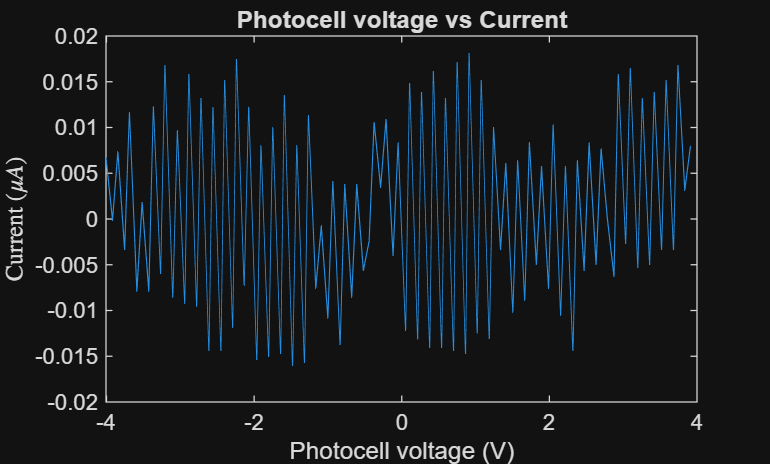

data = readtable("dark.txt");
intensity = data{:, 2};
position = data{:, 1};
plot(position, intensity);
xlabel("Photocell voltage (V)");
ylabel("Current (\(\mu A)\)", "Interpreter","latex");
title("Photocell voltage vs Current");


difference = diff(intensity);
noise = mean(difference)*1e6

noise = 13.2644

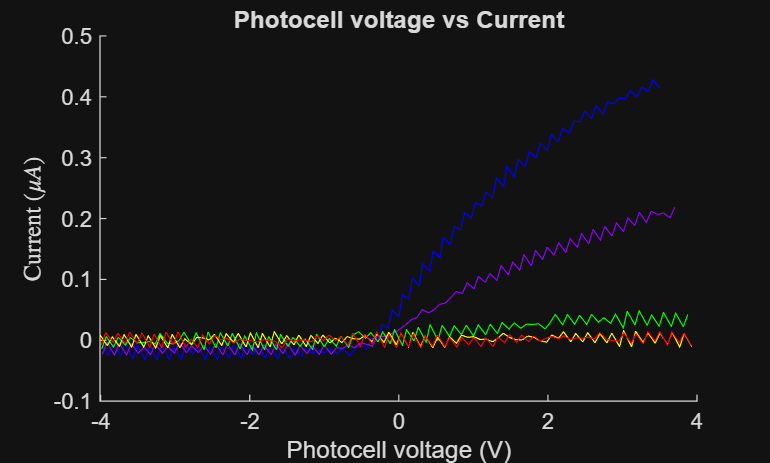


figure;
hold on;
data = readtable("blue.txt");
intensity = data{:, 2};
position = data{:, 1};
plot(position, intensity, "Color","blue");

data = readtable("uv.txt");
intensity = data{:, 2};
position = data{:, 1};
plot(position, intensity, "Color","#8F00FF");

data = readtable("green.txt");
intensity = data{:, 2};
position = data{:, 1};
plot(position, intensity, "Color","green");

data = readtable("yellow.txt");
intensity = data{:, 2};
position = data{:, 1};
plot(position, intensity, "Color","yellow");

data = readtable("red.txt");
intensity = data{:, 2};
position = data{:, 1};
plot(position, intensity, "Color","red");

xlabel("Photocell voltage (V)");
ylabel("Current (\(\mu A)\)", "Interpreter","latex");
title("Photocell voltage vs Current")

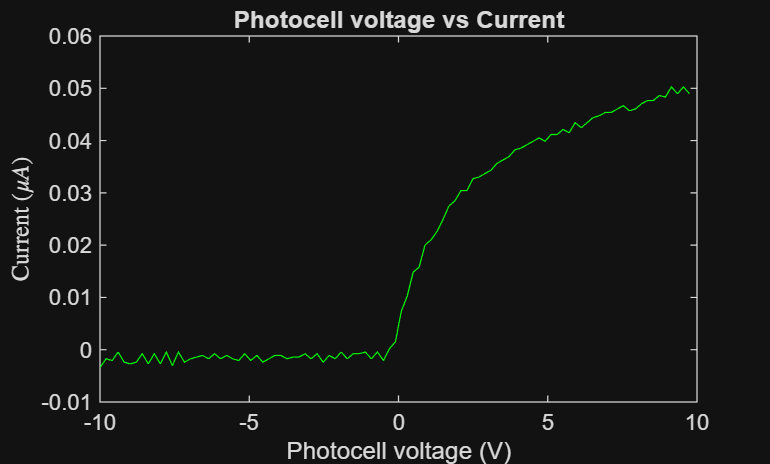


figure;
data = readtable("green_wide.txt");
intensity = data{:, 2};
position = data{:, 1};
plot(position, intensity, "Color","green");
xlabel("Photocell voltage (V)");
ylabel("Current (\(\mu A)\)", "Interpreter","latex");
title("Photocell voltage vs Current");

## Task 7:

Uth_arr = zeros(5,1)

Uth_arr =      0
     0
     0
     0
     0


wavelengths = [0.3993,0.4670,0.5219,0.5813,0.6194];
c = 2.9992458 * 1e8* 1e6;
Freq_arr = c ./ wavelengths

Freq_arr = 1.0e+14 *

    7.5113    6.4224    5.7468    5.1595    4.8422


figure;
hold on;
data = readtable("uv.txt");
intensity = data{:, 2};
position = data{:, 1};
plot(position, intensity);

constantIntensity = intensity(position < -.5);
constantPosition = position(position < -.5);
constFit = polyfit(constantPosition,constantIntensity,1);
constSlope = constFit(1)

constSlope = 5.3375e-04

constIntercept = constFit(2)

constIntercept = -0.0133

x = linspace(-4,4,100);
plot(x,constIntercept + x * constSlope);

linIntensity = intensity(position > 0 & position < 1);
linPosition = position(position > 0 & position < 1);
linFit = polyfit(linPosition, linIntensity, 1);
linSlope = linFit(1)

linSlope = 0.0746

linIntercept = linFit(2)

linIntercept = 0.0190

plot(x, linIntercept + linSlope * x);

Uth = (constIntercept - linIntercept) / (linSlope - constSlope)

Uth = -0.4363

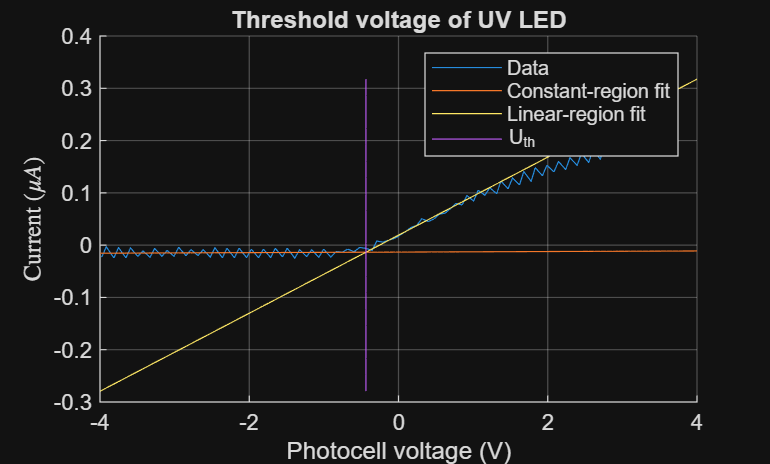

Ith = linIntercept + linSlope*Uth;
plot(linspace(Uth,Uth,20),linspace(linIntercept + -4*linSlope, linIntercept + 4*linSlope,20))

xlabel("Photocell voltage (V)");
ylabel("Current (\(\mu A)\)", "Interpreter","latex");
legend("Data", "Constant-region fit", "Linear-region fit","U_{th}");
title("Threshold voltage of UV LED")
grid on;

Uth_arr(1) = Uth;


figure;
hold on;
data = readtable("blue.txt");
intensity = data{:, 2};
position = data{:, 1};
plot(position, intensity);

constantIntensity = intensity(position < -.5);
constantPosition = position(position < -.5);
constFit = polyfit(constantPosition,constantIntensity,1);
constSlope = constFit(1)

constSlope = 3.3641e-05

constIntercept = constFit(2)

constIntercept = -0.0180

x = linspace(-4,4,100);
plot(x,constIntercept + x * constSlope);

linIntensity = intensity(position > 0 & position < 1);
linPosition = position(position > 0 & position < 1);
linFit = polyfit(linPosition, linIntensity, 1);
linSlope = linFit(1)

linSlope = 0.1608

linIntercept = linFit(2)

linIntercept = 0.0572

plot(x, linIntercept + linSlope * x);

Uth = (constIntercept - linIntercept) / (linSlope - constSlope)

Uth = -0.4674

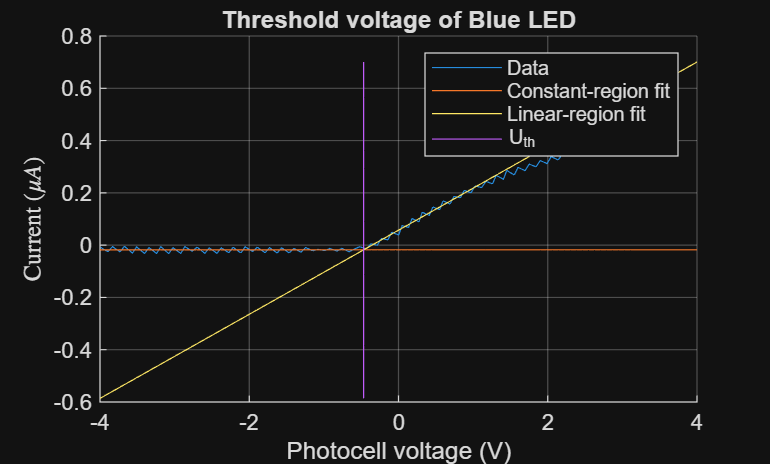

Ith = linIntercept + linSlope*Uth;
plot(linspace(Uth,Uth,20),linspace(linIntercept + -4*linSlope, linIntercept + 4*linSlope,20))

xlabel("Photocell voltage (V)");
ylabel("Current (\(\mu A)\)", "Interpreter","latex");
legend("Data", "Constant-region fit", "Linear-region fit","U_{th}");
title("Threshold voltage of Blue LED")
grid on;


Uth_arr(2) = Uth;

figure;
hold on;
data = readtable("green.txt");
intensity = data{:, 2};
position = data{:, 1};
plot(position, intensity);

constantIntensity = intensity(position < -.5);
constantPosition = position(position < -.5);
constFit = polyfit(constantPosition,constantIntensity,1);
constSlope = constFit(1)

constSlope = 4.3016e-04

constIntercept = constFit(2)

constIntercept = -3.2807e-04

x = linspace(-4,4,100);
plot(x,constIntercept + x * constSlope);

linIntensity = intensity(position > 0 & position < 1);
linPosition = position(position > 0 & position < 1);
linFit = polyfit(linPosition, linIntensity, 1);
linSlope = linFit(1)

linSlope = 0.0184

linIntercept = linFit(2)

linIntercept = 0.0030

plot(x, linIntercept + linSlope * x);

Uth = (constIntercept - linIntercept) / (linSlope - constSlope)

Uth = -0.1873

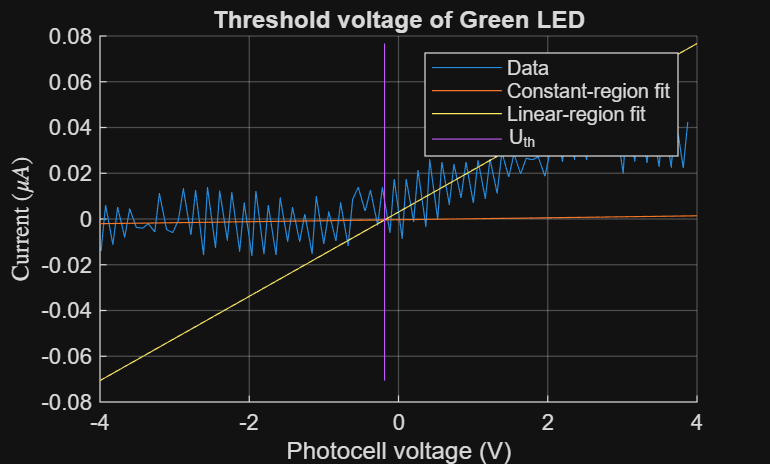

Ith = linIntercept + linSlope*Uth;
plot(linspace(Uth,Uth,20),linspace(linIntercept + -4*linSlope, linIntercept + 4*linSlope,20))

xlabel("Photocell voltage (V)");
ylabel("Current (\(\mu A)\)", "Interpreter","latex");
legend("Data", "Constant-region fit", "Linear-region fit","U_{th}");
title("Threshold voltage of Green LED")
grid on;


Uth_arr(3) = Uth;

figure;
hold on;
data = readtable("yellow_wide.txt");
intensity = data{:, 2};
position = data{:, 1};
plot(position, intensity);

constantIntensity = intensity(position > -7.5 & position < -2.5);
constantPosition = position(position > -7.5 & position < -2.5);
constFit = polyfit(constantPosition,constantIntensity,1);
constSlope = constFit(1)

constSlope = 2.7996e-06

constIntercept = constFit(2)

constIntercept = 6.5592e-04

x = linspace(-10,10,100);
plot(x,constIntercept + x * constSlope);

linIntensity = intensity(position > 0 & position < 5);
linPosition = position(position > 0 & position < 5);
linFit = polyfit(linPosition, linIntensity, 1);
linSlope = linFit(1)

linSlope = 1.8787e-04

linIntercept = linFit(2)

linIntercept = 9.2184e-04

plot(x, linIntercept + linSlope * x);

Uth = (constIntercept - linIntercept) / (linSlope - constSlope)

Uth = -1.4369

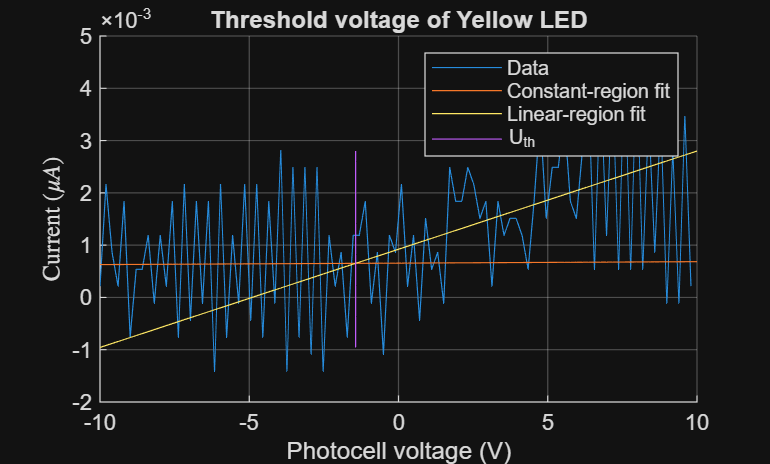

Ith = linIntercept + linSlope*Uth;
plot(linspace(Uth,Uth,20),linspace(linIntercept + -10*linSlope, linIntercept + 10*linSlope,20))

xlabel("Photocell voltage (V)");
ylabel("Current (\(\mu A)\)", "Interpreter","latex");
legend("Data", "Constant-region fit", "Linear-region fit","U_{th}");
title("Threshold voltage of Yellow LED")
grid on;


Uth_arr(4) = Uth;

figure;
hold on;
data = readtable("red_wide.txt");
intensity = data{:, 2};
position = data{:, 1};
plot(position, intensity);

constantIntensity = intensity(position < -2);
constantPosition = position(position < -2);
constFit = polyfit(constantPosition,constantIntensity,1);
constSlope = constFit(1)

constSlope = 3.3626e-05

constIntercept = constFit(2)

constIntercept = 7.9064e-04

x = linspace(-10,10,100);
plot(x,constIntercept + x * constSlope);

linIntensity = intensity(position > 1 & position < 7);
linPosition = position(position > 1 & position < 7);
linFit = polyfit(linPosition, linIntensity, 1);
linSlope = linFit(1)

linSlope = 1.6809e-04

linIntercept = linFit(2)

linIntercept = 8.7737e-04

plot(x, linIntercept + linSlope * x);

Uth = (constIntercept - linIntercept) / (linSlope - constSlope)

Uth = -0.6450

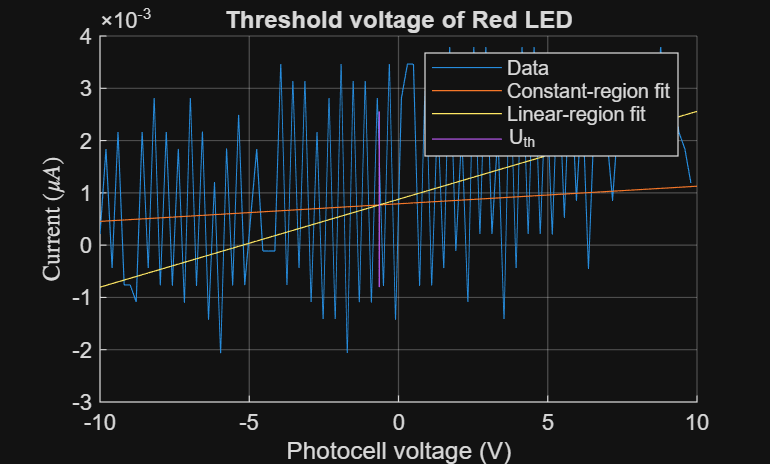

Ith = linIntercept + linSlope*Uth;
plot(linspace(Uth,Uth,20),linspace(linIntercept + -10*linSlope, linIntercept + 10*linSlope,20))

xlabel("Photocell voltage (V)");
ylabel("Current (\(\mu A)\)", "Interpreter","latex");
legend("Data", "Constant-region fit", "Linear-region fit","U_{th}");
title("Threshold voltage of Red LED")
grid on;

Uth_arr(5) = Uth;

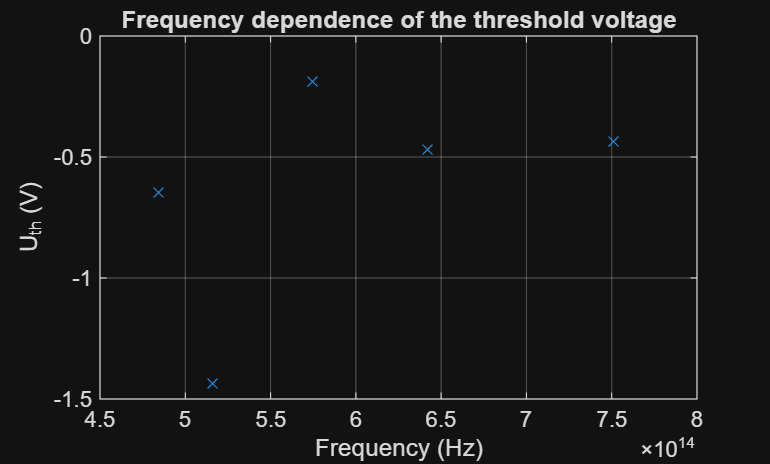

figure;
plot(Freq_arr,Uth_arr,'LineStyle','none','Marker','x')
ylabel("U_{th} (V)")
xlabel("Frequency (Hz)")
title("Frequency dependence of the threshold voltage")
grid on;

Since the energies of the red and the yellow LEDs are small, the noise is much more severe when it comes to plotting.

## Task 8:

U = Uth_arr(1:3)

U =    -0.4363
   -0.4674
   -0.1873


f = Freq_arr(1:3)

f = 1.0e+14 *

    7.5113    6.4224    5.7468



linearFit = polyfit(f, U, 1);
planckSlope = linearFit(1)

planckSlope = -1.2506e-15

planckIntercept = linearFit(2)

planckIntercept = 0.4568


e = -1.6e-19;
h = planckSlope * e

h = 2.0009e-34

W = planckIntercept * e

W = -7.3081e-20


W_ev = W*6.2415e18

W_ev = -0.4561

## Task 9:

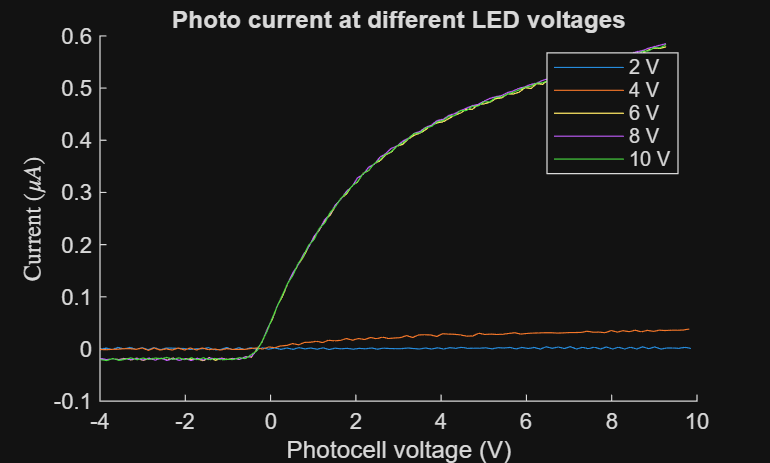

figure;
hold on;
data = readtable("task9_2.txt");
intensity = data{:, 2};
position = data{:, 1};
plot(position, intensity);
data = readtable("task9_4.txt");
intensity = data{:, 2};
position = data{:, 1};
plot(position, intensity);
data = readtable("task9_6.txt");
intensity = data{:, 2};
position = data{:, 1};
plot(position, intensity);
data = readtable("task9_8.txt");
intensity = data{:, 2};
position = data{:, 1};
plot(position, intensity);
data = readtable("task9_10.txt");
intensity = data{:, 2};
position = data{:, 1};
plot(position, intensity);
xlabel("Photocell voltage (V)");
ylabel("Current (\(\mu A)\)", "Interpreter","latex");
legend("2 V", "4 V", "6 V","8 V", "10 V");
title("Photo current at different LED voltages")

## Measurement 2

## Task 10:

The aquired turn on voltages are:

UV LED: 2.3898 Volts

Blue LED: 2.1659 Volts

Green LED: 1.8716 Volts

Yellow LED: 1.5093 Volts

Red LED: 1.3679 Volts

Uto_arr = zeros(5,1);

UV:

figure;
hold on;
data = readtable("T10Uv.txt");
intensity = data{:, 2};
position = data{:, 1};
plot(position, intensity);

constantIntensity = intensity(position < 2);
constantPosition = position(position < 2);
constFit = polyfit(constantPosition,constantIntensity,1);
constSlope = constFit(1);
constIntercept = constFit(2);
x = linspace(-4,4,100);
y = constIntercept + x * constSlope;
plot(x(y > -.5 & y < 3),y(y > -.5 & y < 3));

linIntensity = intensity(position > 2.36 & position < 4);
linPosition = position(position > 2.36 & position < 4);
linFit = polyfit(linPosition, linIntensity, 1);
linSlope = linFit(1);
linIntercept = linFit(2);
y = linIntercept + linSlope * x;
plot(x(y > -.5 & y < 3), y(y > -.5 & y < 3));

Uth = (constIntercept - linIntercept) / (linSlope - constSlope)

Uth = 2.3898

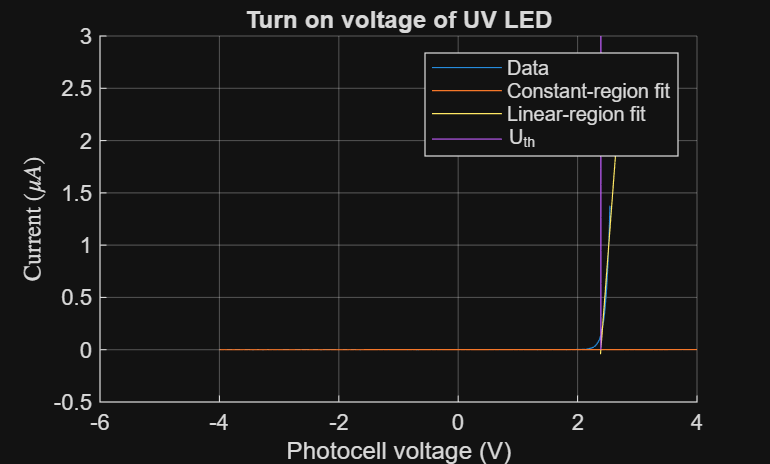

Ith = linIntercept + linSlope*Uth;
plot(linspace(Uth,Uth,20),linspace(0, 3,20))

xlabel("Photocell voltage (V)");
ylabel("Current (\(\mu A)\)", "Interpreter","latex");
legend("Data", "Constant-region fit", "Linear-region fit","U_{o}");
title("Turn on voltage of UV LED")
grid on;

Uto_arr(1) = Uth;


Blue:

figure;
hold on;
data = readtable("T10Blue.txt");
intensity = data{:, 2};
position = data{:, 1};
plot(position, intensity);

constantIntensity = intensity(position < 0);
constantPosition = position(position < 0);
constFit = polyfit(constantPosition,constantIntensity,1);
constSlope = constFit(1);
constIntercept = constFit(2);
x = linspace(-4,4,100);
y = constIntercept + x * constSlope;
plot(x(y > -.5 & y < 3),y(y > -.5 & y < 3));

linIntensity = intensity(position > 2.1 & position < 4);
linPosition = position(position > 2.1 & position < 4);
linFit = polyfit(linPosition, linIntensity, 1);
linSlope = linFit(1);
linIntercept = linFit(2);
y = linIntercept + linSlope * x;
plot(x(y > -.5 & y < 3), y(y > -.5 & y < 3));

Uth = (constIntercept - linIntercept) / (linSlope - constSlope)

Uth = 2.1659

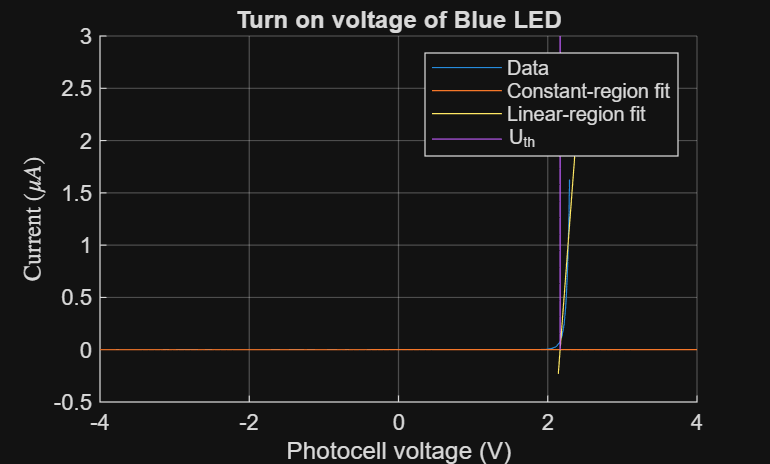

Ith = linIntercept + linSlope*Uth;
plot(linspace(Uth,Uth,20),linspace(0, 3,20))

xlabel("Photocell voltage (V)");
ylabel("Current (\(\mu A)\)", "Interpreter","latex");
legend("Data", "Constant-region fit", "Linear-region fit","U_{o}");
title("Turn on voltage of Blue LED")
grid on;

Uto_arr(2) = Uth;

Green:

figure;
hold on;
data = readtable("T10Green.txt");
intensity = data{:, 2};
position = data{:, 1};
plot(position, intensity);

constantIntensity = intensity(position < 0);
constantPosition = position(position < 0);
constFit = polyfit(constantPosition,constantIntensity,1);
constSlope = constFit(1);
constIntercept = constFit(2);
x = linspace(-4,4,100);
y = constIntercept + x * constSlope;
plot(x(y > -.5 & y < 3),y(y > -.5 & y < 3));

linIntensity = intensity(position > 1.8 & position < 4);
linPosition = position(position > 1.8 & position < 4);
linFit = polyfit(linPosition, linIntensity, 1);
linSlope = linFit(1);
linIntercept = linFit(2);
y = linIntercept + linSlope * x;
plot(x(y > -.5 & y < 3), y(y > -.5 & y < 3));

Uth = (constIntercept - linIntercept) / (linSlope - constSlope)

Uth = 1.8716

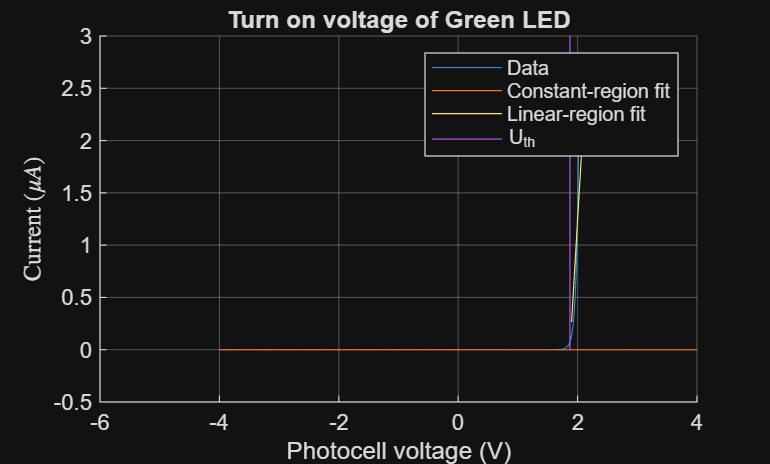

Ith = linIntercept + linSlope*Uth;
plot(linspace(Uth,Uth,20),linspace(0, 3,20))

xlabel("Photocell voltage (V)");
ylabel("Current (\(\mu A)\)", "Interpreter","latex");
legend("Data", "Constant-region fit", "Linear-region fit","U_{o}");
title("Turn on voltage of Green LED")
grid on;

Uto_arr(3) = Uth;

Yellow:

figure;
hold on;
data = readtable("T10Yellow.txt");
intensity = data{:, 2};
position = data{:, 1};
plot(position, intensity);

constantIntensity = intensity(position < 0);
constantPosition = position(position < 0);
constFit = polyfit(constantPosition,constantIntensity,1);
constSlope = constFit(1)

constSlope = 1.5931e-04

constIntercept = constFit(2)

constIntercept = -0.0014

x = linspace(-4,4,100);
y = constIntercept + x * constSlope;
plot(x(y > -.5 & y < 3),y(y > -.5 & y < 3));

linIntensity = intensity(position > 1.49 & position < 4);
linPosition = position(position > 1.49 & position < 4);
linFit = polyfit(linPosition, linIntensity, 1);
linSlope = linFit(1);
linIntercept = linFit(2);
y = linIntercept + linSlope * x;
plot(x(y > -.5 & y < 3), y(y > -.5 & y < 3));

Uth = (constIntercept - linIntercept) / (linSlope - constSlope)

Uth = 1.5093

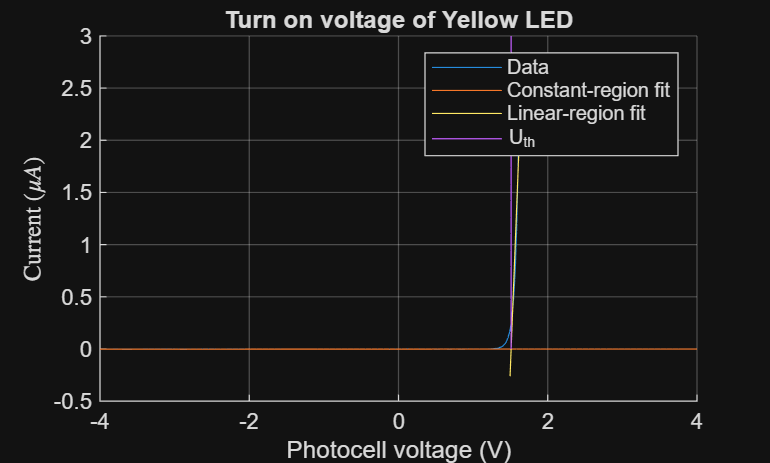

Ith = linIntercept + linSlope*Uth;
plot(linspace(Uth,Uth,20),linspace(0, 3,20))

xlabel("Photocell voltage (V)");
ylabel("Current (\(\mu A)\)", "Interpreter","latex");
legend("Data", "Constant-region fit", "Linear-region fit","U_{o}");
title("Turn on voltage of Yellow LED")
grid on;

Uto_arr(4) = Uth;

Red:

figure;
hold on;
data = readtable("T10Red.txt");
intensity = data{:, 2};
position = data{:, 1};
plot(position, intensity);

constantIntensity = intensity(position < 0);
constantPosition = position(position < 0);
constFit = polyfit(constantPosition,constantIntensity,1);
constSlope = constFit(1)

constSlope = 3.3578e-04

constIntercept = constFit(2)

constIntercept = -0.0020

x = linspace(-4,4,100);
y = constIntercept + x * constSlope;
plot(x(y > -.5 & y < 3),y(y > -.5 & y < 3));

linIntensity = intensity(position > 1.32 & position < 4);
linPosition = position(position > 1.32 & position < 4);
linFit = polyfit(linPosition, linIntensity, 1);
linSlope = linFit(1);
linIntercept = linFit(2);
y = linIntercept + linSlope * x;
plot(x(y > -.5 & y < 3), y(y > -.5 & y < 3));

Uth = (constIntercept - linIntercept) / (linSlope - constSlope)

Uth = 1.3679

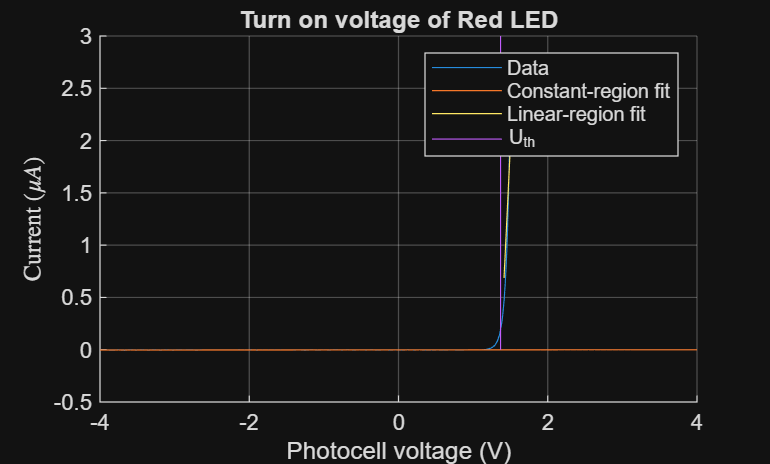

Ith = linIntercept + linSlope*Uth;
plot(linspace(Uth,Uth,20),linspace(0, 3,20))

xlabel("Photocell voltage (V)");
ylabel("Current (\(\mu A)\)", "Interpreter","latex");
legend("Data", "Constant-region fit", "Linear-region fit","U_{o}");
title("Turn on voltage of Red LED")
grid on;

Uto_arr(5) = Uth;

## Task 11:

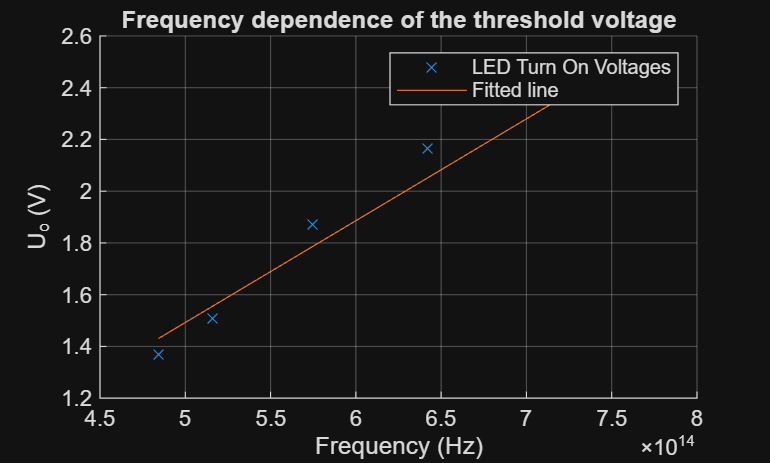

figure;
hold on;
plot(Freq_arr,Uto_arr,'LineStyle','none','Marker','x')
ylabel("U_{o} (V)")
xlabel("Frequency (Hz)")
title("Frequency dependence of the threshold voltage")
grid on;

U = Uto_arr(1:5);
f = Freq_arr(1:5);

linearFit = polyfit(f, U, 1);
planckSlope = linearFit(1);
planckIntercept = linearFit(2);
plot(f,planckIntercept + planckSlope*f)
legend("LED Turn On Voltages", "Fitted line")


e = -1.6e-19;
h = abs(planckSlope * e)

h = 6.2964e-34

%W = planckIntercept * e

%W_ev = W*6.2415e18

## Task 12:

% Calculating the drive voltage
Il = 2e-3;
R = 220;
Ud_min = (Il*R) + Uto_arr

Ud_min =     2.8298
    2.6059
    2.3116
    1.9493
    1.8079



Il = 30e-3;
Ud_max = 5.34 %s (Il*R) + Uto_arr

Ud_max = 5.3400


Ud = linspace(Ud_min(2),Ud_max,10)

Ud =     2.6059    2.9097    3.2135    3.5173    3.8211    4.1248    4.4286    4.7324    5.0362    5.3400


figure;
hold on;
data = readtable("T12_1.txt");
intensity = data{:, 2};
position = data{:, 1};
plot(position, intensity);
data = readtable("T12_2.txt");
intensity = data{:, 2};
position = data{:, 1};
plot(position, intensity);
data = readtable("T12_3.txt");
intensity = data{:, 2};
position = data{:, 1};
plot(position, intensity);
data = readtable("T12_4.txt");
intensity = data{:, 2};
position = data{:, 1};
plot(position, intensity);
data = readtable("T12_5.txt");
intensity = data{:, 2};
position = data{:, 1};
plot(position, intensity);
data = readtable("T12_6.txt");
intensity = data{:, 2};
position = data{:, 1};
plot(position, intensity);
data = readtable("T12_7.txt");
intensity = data{:, 2};
position = data{:, 1};
plot(position, intensity);
data = readtable("T12_8.txt");
intensity = data{:, 2};
position = data{:, 1};
plot(position, intensity);
data = readtable("T12_9.txt");
intensity = data{:, 2};
position = data{:, 1};
plot(position, intensity);
data = readtable("T12_10.txt");
intensity = data{:, 2};
position = data{:, 1};
plot(position, intensity);
Il = round((Ud - Uto_arr(2)) ./ R * 1e3, 3)

Il =     2.0000    5.1110    8.2220   11.3330   14.4440   17.5560   20.6670   23.7780   26.8890   30.0000


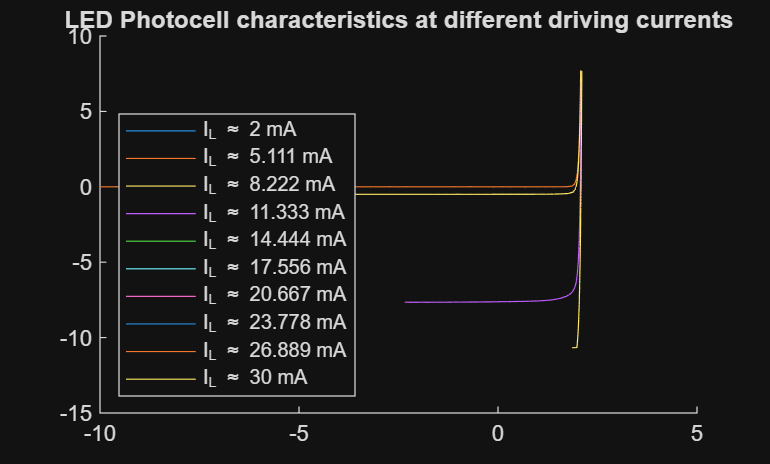

title("LED Photocell characteristics at different driving currents")
legend("I_L \approx {"+Il(1)+" mA}","I_L \approx {"+Il(2)+" mA}","I_L \approx {"+Il(3) ...
    +" mA}","I_L \approx {"+Il(4)+" mA}","I_L \approx {"+Il(5)+" mA}","I_L \approx {"+Il(6) ...
    +" mA}","I_L \approx {"+Il(7)+" mA}","I_L \approx {"+Il(8)+" mA}","I_L \approx {"+Il(9)+" mA}", ...
    "I_L \approx {"+Il(10)+" mA}","Location","southwest")